# Testing del metodo di Jacobi

### Casi d'uso

Si testa il software su matrici sparse di notevoli dimensioni, generate usando funzioni Matlab non singolari e ben condizionate. Si illustra, attraverso grafico, la struttura delle matrici di test. Un primo esempio di matrice ben condizionata:

n = 5000;
e = ones(n,1);
Z = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
spy(Z)
b = Z*e;
c = condest(Z)
[sol, niter] = Jacobi(Z, b);
niter

Esempio d'uso nel caso in cui l'utente specifichi il valore di tolleranza:

n = 5000;
e = ones(n,1);
Z = spdiags([e 6*e 10*e -e e], [-1500 -800 0 2600 2800], n, n);
spy(Z)
b = Z*e;
c = condest(Z)
[sol, niter] = Jacobi(Z, b, 10^-9);
niter

Esempio d'uso nel caso in cui l'utente specifichi il valore di tolleranza e il numero massimo di iterazioni:

X = gallery('poisson',40);
spy(X)
size(X)
condest(X)
x = ones(1600,1);
b = X*x;
[sol, niter] = Jacobi(X,b,10^-6,3000)
niter

Si noti che, essendo aumentato il raggio spettrale, l'algoritmo converge in un numero maggiore di iterazioni.

### Casi di errore

Utilizziamo la matrice sparsa di Toeppen che presenta elementi nulli sulla diagonale. Per questo tipo di matrici, il metodo di Jacobi non è definito.

T = gallery('toeppen',1000);
spy(T)
b = T*ones(1000,1);
[sol6, niter6] = Jacobi(T,b);
niter6
sol6

### Test di accuratezza

n = 5000;
e = ones(n,1);
Z = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
b = Z*e;
c = condest(Z)

c =      2.269252419481775e+00


[sol, niter, res] = Jacobi(Z, b)

Raggio spettrale:
     3.306146307515894e-01



sol =      1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00
     1.000000000444483e+00


niter =     11


res =      6.623950529603319e-08


err = norm(e-sol)/norm(sol)

err =      2.969125980155711e-08


res

res =      6.623950529603319e-08


[sol, niter, res] = Jacobi(Z, b, 10^-13)

Raggio spettrale:
     3.306146307515894e-01



sol =      9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01
     9.999999999999959e-01


niter =     24


res =      1.234100541057016e-14


err = norm(e-sol)/norm(sol)

err =      9.608773431926683e-15


### Velocità di convergenza

Nei paragrafi precedenti è stato già notato come, all'aumentare del condizionamento e del raggio spettrale, la function converga in un numero di iterazioni maggiore. Mostriamo qui alcuni esempi.

### Casi di warning

Potrebbe capitare che il numero di iterazioni massimo non sia sufficiente per ottenere il numero di cifre significative desiderato. Mostriamo di seguito alcuni esempi:

X = gallery('poisson',45);
condest(X)

ans =    1.2466e+03


x = ones(2025,1);
b = X*x;
[sol, niter] = Jacobi(X,b,10^-6,1000)

sol =    9.9927e-01
   9.9854e-01
   9.9783e-01
   9.9712e-01
   9.9642e-01
   9.9574e-01
   9.9508e-01
   9.9445e-01
   9.9384e-01
   9.9325e-01


niter =         1000


[sol, niter] = Jacobi(X,b,10^-6,4000)

sol =    1.0000e+00
   1.0000e+00
   9.9999e-01
   9.9999e-01
   9.9999e-01
   9.9999e-01
   9.9999e-01
   9.9998e-01
   9.9998e-01
   9.9998e-01


niter =         3529


In questo caso, dato che il primo numero massimo di iterazioni è stato impostato a 1000, la function stampa un messaggio di warning specificando che il risultato potrebbe non soddisfare l'accuratezza richiesta. Se si aumenta tale parametro, la function converge al risultato con accuratezza corretta.

Il prossimo esempio, invece, mostra una matrice malcondizionata con raggio spettrale uguale a 1. In questo caso, il metodo iterativo di Jacobi non converge.

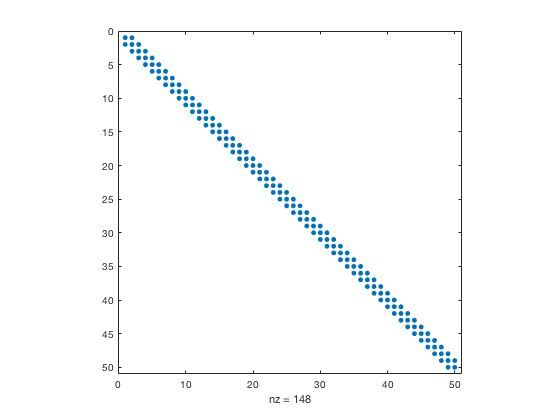

D = gallery('dorr',50);
spy(D)

b = D*ones(50,1);
[sol5, niter5] = Jacobi(D,b,10^-6,30000)

sol5 =    5.6895e-01
   3.4698e-01
   2.3038e-01
   1.6786e-01
   1.3364e-01
   1.1450e-01
   1.0357e-01
   9.7186e-02
   9.3374e-02
   9.1046e-02


niter5 =        30000


niter5

niter5 =        30000


caso in cui diagonale non strettamente dominante e buon condizionamento

% (vale per tutti i tol)

% NON CONVERGE anche con Tol = 10^-15 e aumentando le iterazioni.

W = spdiags([e 5*e 2*e -e e], [-1300 -500 0 400 2500], n, n);
spy(W);
b = W*e;
[sol4, niter4] = Jacobi(W,b,10^(-15));
niter4